# Ionostasis at the Tripatite Synapse - CNS 2022 Tutorial

By Marinus Toman, Liam McDaid and John Wade.

## Introduction to the Tripartite Synapse

The *tripartite synapse* is a term used to acknowledge the important contribution of astrocytes to neuronal synapses. A neuronal synapse consists of a pre and postsynaptic cell (two cells), while a tripartite synapse consists of a neuronal synapse with a neighbouring astrocyte (three cells). Figure 1 shows a schematic of the cells, channels and transporters at a typical tripartite synapse. An important role carried out by astrocytes at the tripartite synapse is *homeostasis*; restoring equilibrium after perturbations of ionic concentrations during synaptic transmission. The ions/molecules considered in the homeostasis model are glutamate (Glu), potassium (K), sodium (Na) and calcium (Ca). 

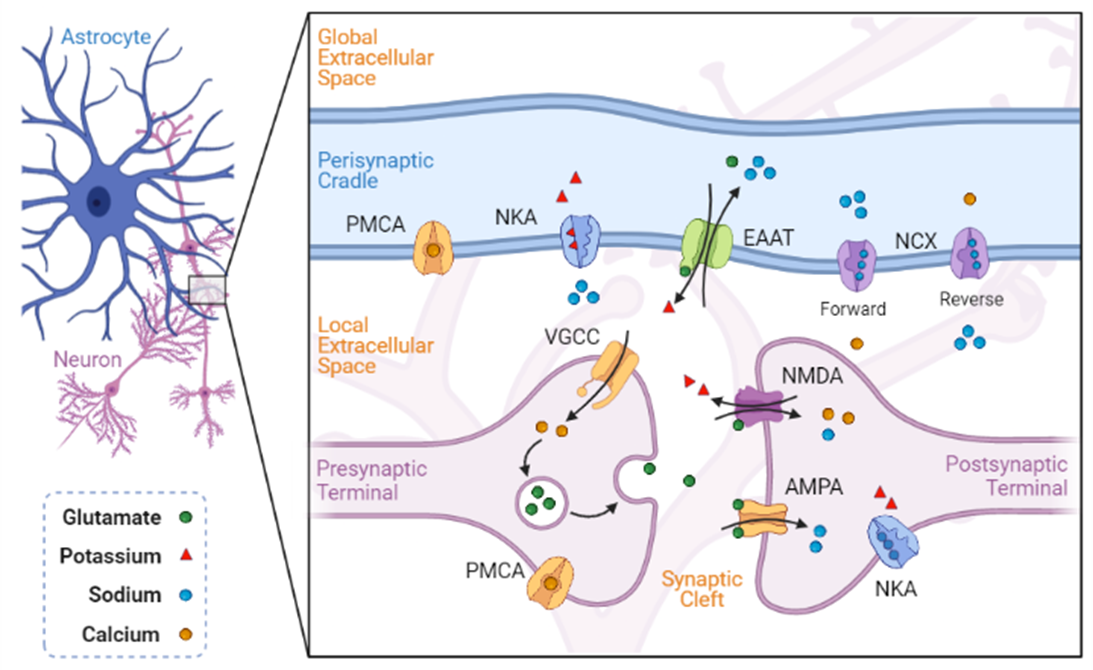

Figure 1. Tripartite synapse schematic. 

For demonstration purposes, we will only consider the presynaptic cell (modelled using the HH model) and the astrocyte perisynaptic cradle (modelled using the same techniques as the HH model). This is enough to demonstrate astrocytic homeostasis during synaptic transmission.

The demonstration is split into two parts; first the HH model is solved, then the astrocyte model is solved. Results are plotted to show neuron-astrocyte interactions and astrocytic homeostasis over time.

## Section 1 - Solving the HH Model with MATLAB's ODE Solver

The HH model of a neuronal action potential (AP) is a system of four ordinary differential equations (ODEs) that describe the rapid change in neuronal membrane potential over time [1]. The ODEs are provided in the HHModel function and are given [1]:

#### 
$$C\frac{dV_m }{\mathrm{dt}}=I_{\mathrm{ext}} -\left(I_{\mathrm{Na}} +I_K +I_{\mathrm{Ca}} +I_L \right)$$


#### 
$$I_{\mathrm{Na}} =g_{\mathrm{Na}} m^3 h\left(V_m -E_{\mathrm{Na}} \right)$$


#### 
$$I_K =g_K n^4 \left(V_m -E_K \right)$$


#### 
$$I_{\mathrm{Ca}} =g_{\mathrm{Ca}} r\left(V_m -E_{\mathrm{Ca}} \right)$$


#### 
$$I_L =g_L \left(V_m -E_L \right)$$


#### 
$$\frac{\mathrm{dx}}{\mathrm{dt}}=\alpha_x \left(1-x\right)-\beta_x x$$


#### 
$$x\in \left\lbrace m,h,n,r\right\rbrace$$


Feel free to explore the HHModel function and study how the equations are coded. To run the system of ODEs, we will use a built-in MATLAB ODE solver; *ode45*.

Before we start, let's clear the MATLAB environment.

clear

#### 1 - Set the initial conditions

The first thing we need to do is set up the initial conditions of the system. This includes defining initial ionic concentrations, initial membrane potential e.t.c, while also setting some known constants like the simulation duration, the ionic valency and Faraday’s constant (the amount of charge per mole of substance). For this tutorial, we will use the code below. See the comments for a description of each parameter.

simTime = 200;%simulation time (ms)
Vm      = -60;% resting membrane potential (mV)
Ca_i    = 50e-9;% resting intracellular Ca
Ca_e    = 1.5e-3;% resting extracellular Ca
Glu     = 0;%initial glutamate
[am,bm,ah,bh,an,bn,m_inf,~] = gating(Vm);% get initial gating variable states
m       = am/(am+bm);%Na activation
h       = ah/(ah+bh);%Na inactivation
n       = an/(an+bn);%K activation
r       = m_inf;%Ca activation
F       = 96485.33;% Faradays constant; unit: C/mol;

#### 2 - Set parameters for the ODE solver

Next, we need to set up the parameters for the ODE solver, this includes setting the time range and storing the initial conditions in a format the solver expects; a vector of initial conditions.

tRange  = [0,simTime];% time range
Y0      = [Vm;m;h;n;r;Ca_i;Ca_e;Glu];% initial conditions

#### 3 - Define the HH model as a set of ODEs

For purposes of the tutorial, the HH model has been provided as a system of ODEs in a format suitable for the MATLAB ODE solver (HH Model). Feel free to explore the HH system of ODEs. 

For information on how to format the equations for the MATLAB ODE solver, see [https://uk.mathworks.com/help/matlab/math/choose-an-ode-solver.html](https://uk.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

For examples of the ODE solver being used to solve different ODEs, see [https://uk.mathworks.com/help/matlab/examples.html?category=ordinary-differential-equations](https://uk.mathworks.com/help/matlab/examples.html?category=ordinary-differential-equations)

#### 4 - Solve HH model using MATLAB's ODE solver

Now that everything is set up, we can run the system using MATLAB's built-in ODE solver.

[t, YSol] = ode45(@HHModel,tRange,Y0);

#### 5 - Get results from solution vector

Now the system has been solved, we can retrieve the results from the solution vector:

Vm      = YSol(:,1);
m       = YSol(:,2);
h       = YSol(:,3);
n       = YSol(:,4);
r       = YSol(:,5);
Ca_i    = YSol(:,6);
Ca_e    = YSol(:,7);
Glu     = YSol(:,8);

#### 6 - Plot action potential results

Now that the results have been extracted, we can plot the membrane potential to show the action potential firing. We can also plot the ion channel gating variables. The code below uses the ‘subplot’ function and plots a 3x1 figure (shown below the code).

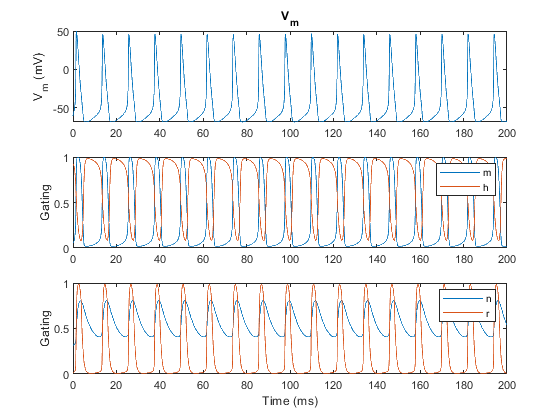

figure(1)
subplot(3,1,1);
plot(t,Vm);
ylabel('V_m (mV)');
title('V_m');
subplot(3,1,2);
plot(t,m,t,h);
ylabel('Gating');
legend('m','h');
subplot(3,1,3);
plot(t,n,t,r);
ylabel('Gating');
legend('n','r');
xlabel('Time (ms)');

#### 7 - Plot Calcium and Glutamate release results

We can also plot the calcium dynamics and the glutamate release in a similar 3x1 figure.

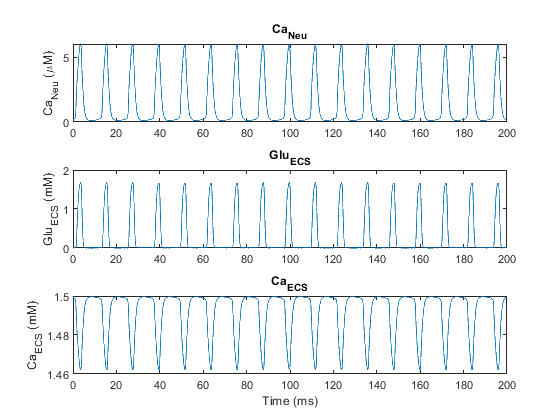

figure(2)
subplot(3,1,1);
plot(t,Ca_i*1e6);
ylabel('Ca_{Neu} (\muM)');
title('Ca_{Neu}');
subplot(3,1,2);
plot(t,Glu*1e3);
ylabel('Glu_{ECS} (mM)');
title('Glu_{ECS}');
subplot(3,1,3);
plot(t,Ca_e*1e3);
ylabel('Ca_{ECS} (mM)');
title('Ca_{ECS}');
xlabel('Time (ms)');

## Section 2 - Solve an Astrocyte Model with Euler's Forward Method

Astrocytes can be modelled at different levels from the network to the cellular level. For this demonstration, we will model at the cellular level and use the same modelling techniques used for the neuron model; embedding ion channels/transporters in the cellular membrane and tracking ionic flows across the membrane. 

To keep things simple, we will only consider the main astrocytic homeostasis channels and transporters known to be present at a typical excitatory tripartite synapse (see Fig. 1). These include the excitatory amino-acid transporter (EAAT2), the Na/K-ATPase (NKA), the Na/Ca exchanger (NCX) and the plasma-membrane Ca-ATPase (PMCA) [2]. The functions for these ion channels have been provided (taken from [3,4]) so please feel free to explore these functions. To run the system of ODEs, we will use Euler's forward method, which approximates the solution of the equations at each small time step (dt) and uses this approximation for the next time step.

#### 1 - Set initial conditions

The first thing we need to do is set up the initial conditions of the system. As before, this includes defining initial ionic concentrations and initial membrane potential e.t.c, while also setting some known constants like the ionic valency and Faraday’s constant (the amount of charge per mole of substance).

dt          = 1e-5;% time step (s)
V_ast       = -0.08;% membrane potential (V)
V0_ast      = -0.08;% resting membrane potential (V)
zNa         = 1;% Na valency
zK          = 1;% K valency
zCa         = 2;% Ca valency
Na_ast      = 15e-3;% Na in astrocyte (M)
Na_psc(1,1) = 15e-3;% Na in cradle (M)
Na_e(1,1)   = 135e-3;% Na in ECS (M)
K_ast       = 100e-3;% K in astrocyte (M)
K_psc(1,1)  = 100e-3;% K in cradle (M)
K_e(1,1)    = 4e-3;% K in ECS (M)
Ca_ast      = 100e-9;% Ca in astrocyte (M)
Ca_psc(1,1) = 100e-9;% Ca in cradle (M)

#### 2 - Set up compartment/cellular morphology

Next, we need to set up the morphology (or shape) of the cells/compartments. When using a point model, all we need to know for each cell is the ***volume*** and the ***surface area***. For demonstration purposes, we have a function to work these numbers out (Model Morphology) [5], so we just call it as follows:

morph = Model_Morphology;

#### 3 - Calculate passive channel conductances

Next, before we start adding ion channels to the membrane, we need to work out what the passive channel conductances would be if the channels were in the membrane. To work out the conductances, we just sum the total active currents crossing the membrane and use some algebra to figure out the passive current which would balance all the active currents. 

**Note:** This step is important as it ensures our system is balanced. 

for i=1:10
    [INa_ncx, ICa_ncx] = NCX(Na_e(1,1),Na_psc(1,1),Ca_e(1,1),Ca_psc(1,1),V_ast);% NCX
    [INa_nka, IK_nka]  = NKA(K_e(1,1),Na_psc(1,1)); % NKA
    ICa_pmca           = PMCA(Ca_psc(1,1)); % PMCA
    % Total currents
    INa_psc = INa_ncx + INa_nka;
    IK_psc  = IK_nka;
    ICa_psc = ICa_ncx + ICa_pmca;
    % Get leak conductances
    gNa_l = Leak_Conduct(INa_psc,Na_e(1,1),Na_psc(1,1),V_ast,zNa);
    gK_l  = Leak_Conduct(IK_psc,K_e(1,1),K_psc(1,1),V_ast,zK);
    gCa_l = Leak_Conduct(ICa_psc,Ca_e(1,1),Ca_psc(1,1),V_ast,zCa);
end

### Solve Euler's Method for Astrocyte

Now we can start to solve the system using Euler's method, one time step at a time in a For loop.

for i = 1:length(Glu)

#### 4 - Add active channels to the astrocyte membrane

Now that the passive channel conductances are known, we can start adding active ion channels to the astrocyte membrane. For this tutorial we will just focus on the main astroglial homeostasis channels that are required at the typical excitatory tripartite synapse; the EAAT2, the NKA, the NCX and the PMCA. The functions for these ion channels/transporters have been provided (Active channels) and can be called as follows:

    [INa_eaat(i,1),IK_eaat(i,1)] = EAAT2(Glu(i,1)); % EAAT
    [INa_ncx(i,1), ICa_ncx(i,1)] = NCX(Na_e(i,1),Na_psc(i,1),Ca_e(i,1),Ca_psc(i,1),V_ast); % NCX
    [INa_nka(i,1), IK_nka(i,1)]  = NKA(K_e(i,1),Na_psc(i,1)); % NKA
    ICa_pmca(i,1)                = PMCA(Ca_psc(i,1)); % PMCA

#### 5 - Add passive channels to the astrocyte membrane

Now that the passive channel conductances are known, we can start also adding passive ion channels to the astrocyte membrane (Passive channels). We will use a generic leak channel for each ion (Na+, K+ and Ca2+).

    INa_l(i,1) = Leak(gNa_l,Na_e(i,1),Na_psc(i,1),V_ast,zNa);
    IK_l(i,1)  = Leak(gK_l,K_e(i,1),K_psc(i,1),V_ast,zK);
    ICa_l(i,1) = Leak(gCa_l,Ca_e(i,1),Ca_psc(i,1),V_ast,zCa);

#### 6 - Add process currents

For model completeness, we must also consider ionic fluxes associated with intracellular diffusion away from the cradle. Here we will assume ions can flow down the astrocyte process. Again, functions have been provided for the process diffusion (Process current) and can be called:

    INa_p(i,1) = Process(Na_ast,Na_psc(i,1),zNa,V_ast,V0_ast,morph.processLength);
    IK_p(i,1)  = Process(K_ast,K_psc(i,1),zK,V_ast,V0_ast,morph.processLength);
    ICa_p(i,1) = Process(Ca_ast,Ca_psc(i,1),zCa,V_ast,V0_ast,morph.processLength);

#### 7 - Convert current densities to absolute currents

So far, we have calculated the density of the currents crossing the whole cell membrane. Now we must calculate the current that crosses our specific surface area of membrane; the absolute currents. This can be done by multiplying our absolute currents by our cell surface area:

    INa_ncx(i,1)    = INa_ncx(i,1) * morph.pscSA; 
    INa_nka(i,1)    = INa_nka(i,1) * morph.pscSA;     
    INa_eaat(i,1)   = INa_eaat(i,1) * morph.pscSA;
    IK_nka(i,1)     = IK_nka(i,1) * morph.pscSA;
    IK_eaat(i,1)    = IK_eaat(i,1) * morph.pscSA;
    ICa_ncx(i,1)    = ICa_ncx(i,1) * morph.pscSA; 
    ICa_pmca(i,1)   = ICa_pmca(i,1) * morph.pscSA;
    ICa_l(i,1)      = ICa_l(i,1) * morph.pscSA;
    IK_l(i,1)       = IK_l(i,1) * morph.pscSA;
    INa_l(i,1)      = INa_l(i,1) * morph.pscSA;
    INa_p(i,1)      = INa_p(i,1) * morph.processCSA;
    IK_p(i,1)       = IK_p(i,1) * morph.processCSA;
    ICa_p(i,1)      = ICa_p(i,1) * morph.processCSA;
    % Total currents
    INa_psc(i,1)    = INa_ncx(i,1) + INa_nka(i,1) + INa_l(i,1) + INa_p(i,1) + INa_eaat(i,1);
    IK_psc(i,1)     = IK_nka(i,1) + IK_l(i,1) + IK_p(i,1) + IK_eaat(i,1);
    ICa_psc(i,1)    = ICa_ncx(i,1) + ICa_l(i,1) + ICa_p(i,1) + ICa_pmca(i,1);
    INa_ecs         = -INa_psc(i,1) + INa_p(i,1);
    IK_ecs          = -IK_psc(i,1) + IK_p(i,1);

#### 8 - Convert absolute currents to fluxes

Once the absolute currents have been calculated, we can figure out the actual flux of ions across the membrane and from the extracellular space (ECS). We can use Faraday’s constant and our cell/compartment volumes for this calculation.

    JNa_psc         = -INa_psc(i,1) * (1 / (zNa*F*morph.pscVol));
    JK_psc          = -IK_psc(i,1) * (1 / (zK*F*morph.pscVol));
    JCa_psc         = -ICa_psc(i,1) * (1 / (zCa*F*morph.pscVol));
    JNa_ecs         = -INa_ecs * (1 / (zNa*F*morph.ecsVol));
    JK_ecs          = -IK_ecs * (1 / (zK*F*morph.ecsVol));

#### 9 - Solve for the concentration at next time step with the fluxes (using Euler’s forward method)

Now the fluxes are known, we can see how much this has changed the respective concentrations. This information is also saved for the next time step.

    Na_psc(i+1,1)   = Na_psc(i,1) + (dt * JNa_psc);
    K_psc(i+1,1)    = K_psc(i,1) + (dt * JK_psc);
    Ca_psc(i+1,1)   = Ca_psc(i,1) + (dt * JCa_psc);
    Na_e(i+1,1)     = Na_e(i,1) + (dt * JNa_ecs);
    K_e(i+1,1)      = K_e(i,1) + (dt * JK_ecs);
end % End of simulation

#### 10 - Plot concentration results

Now that the simulation is done, we can plot the ionic concentrations to see how the astrocyte reacted during the neuronal activity. The code below plots a 3x2 line graph showing the intra/extra-cellular ionic concentrations

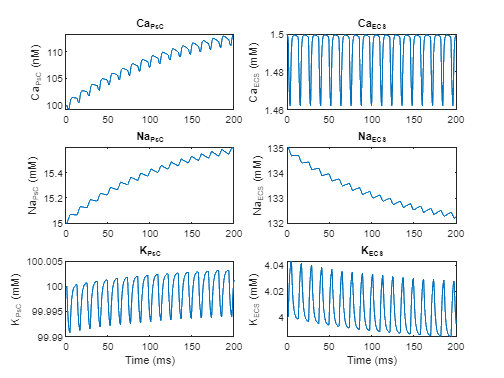

figure(3)
subplot(3,2,1);
plot(t,Ca_psc(1:end-1,1)*1e9);
ylabel('Ca_{PsC} (nM)');
title('Ca_{PsC}');
subplot(3,2,2);
plot(t,Ca_e*1e3);
ylabel('Ca_{ECS} (mM)');
title('Ca_{ECS}');
subplot(3,2,3);
plot(t,Na_psc(1:end-1,1)*1e3);
ylabel('Na_{PsC} (mM)');
title('Na_{PsC}');
subplot(3,2,4);
plot(t,Na_e(1:end-1,1)*1e3);
ylabel('Na_{ECS} (mM)');
title('Na_{ECS}');
subplot(3,2,5);
plot(t,K_psc(1:end-1,1)*1e3);
ylabel('K_{PsC} (mM)');
title('K_{PsC}');
xlabel('Time (ms)');
subplot(3,2,6);
plot(t,K_e(1:end-1,1)*1e3);
ylabel('K_{ECS} (mM)');
title('K_{ECS}');
xlabel('Time (ms)');

#### 11 - Plot Sodium Current Results

We can also plot the astrocyte currents; let's start with the Na currents.

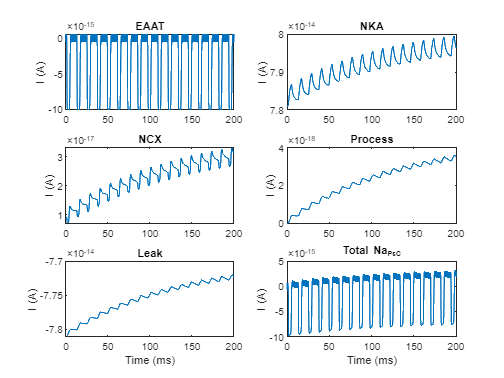

yLab = 'I (A)';
figure(4)
subplot(3,2,1)
plot(t, INa_eaat)
ylabel(yLab)
title('EAAT')
subplot(3,2,2)
plot(t, INa_nka)
ylabel(yLab)
title('NKA')
subplot(3,2,3)
plot(t, INa_ncx)
ylabel(yLab)
title('NCX')
subplot(3,2,4)
plot(t, INa_p)
ylabel(yLab)
title('Process')
subplot(3,2,5)
plot(t,INa_l)
ylabel(yLab)
title('Leak')
xlabel('Time (ms)')
subplot(3,2,6)
plot(t,INa_psc)
ylabel(yLab)
title('Total Na_{PsC}')
xlabel('Time (ms)')

#### 12 - Plot Potassium Current Results

Now let's plot the astrocyte K currents.

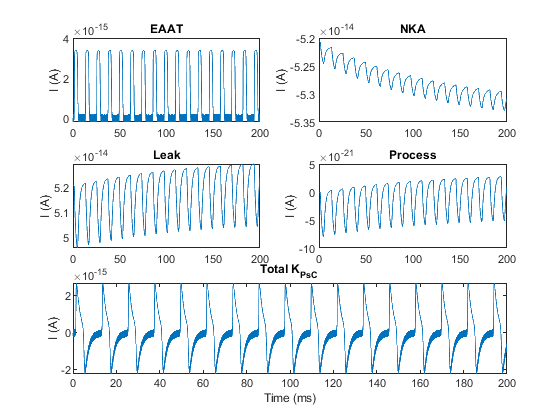

figure(5)
subplot(3,2,1)
plot(t, IK_eaat)
ylabel(yLab)
title('EAAT')
subplot(3,2,2)
plot(t, IK_nka)
ylabel(yLab)
title('NKA')
subplot(3,2,3)
plot(t,IK_l)
ylabel(yLab)
title('Leak')
subplot(3,2,4)
plot(t, IK_p)
ylabel(yLab)
title('Process')
subplot(3,2,[5,6])
plot(t,IK_psc)
ylabel(yLab)
title('Total K_{PsC}')
xlabel('Time (ms)')

#### 13 - Plot Calcium Current Results

And finally, the astrocyte Ca currents

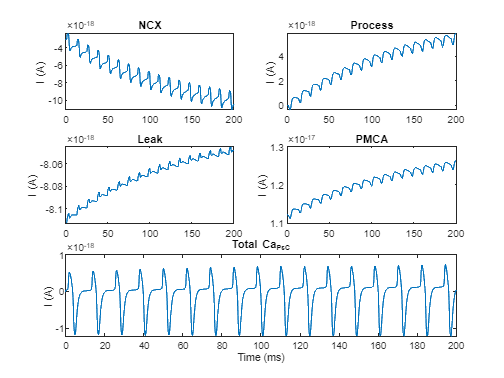

figure(6)
subplot(3,2,1)
plot(t, ICa_ncx)
ylabel(yLab)
title('NCX')
subplot(3,2,2)
plot(t, ICa_p)
ylabel(yLab)
title('Process')
subplot(3,2,3)
plot(t,ICa_l)
ylabel(yLab)
title('Leak')
subplot(3,2,4)
plot(t, ICa_pmca)
ylabel(yLab)
title('PMCA')
subplot(3,2,[5,6])
plot(t,ICa_psc)
ylabel(yLab)
title('Total Ca_{PsC}')
xlabel('Time (ms)')

## HH Model 

#### HH model as a system of ODE's

function dYdt = HHModel(~, Y)
    % get input values
    Vm = Y(1);
    m = Y(2);
    h = Y(3);
    n = Y(4);
    r = Y(5);
    ca_i = Y(6);
    ca_e = Y(7);
    glu = Y(8);
    
    % define constants
    convAmp = 1e-2;%Conversion factor from uA/cm^2 to A/m^2
    Cm = 0.01;
    I_ext = 0.1;
    g_Na = 1.2;%mS/cm2
    g_K = 0.36;%mS/cm2
    g_L = 0.003;%mS/cm2
    g_Ca = 0.01;%mS/cm2
    ENa = 55.17;%mV
    EK = -72.14;%mV
    EL = -49.42;%mV
    ECa = 120;%mV
    ca_i0 = 50e-9;%M
    ca_e0 = 1.5e-3;%M
    glu0 = 0;%M
    tau_ca_pre = 30e-3;%s
    tau_ca_ecs = 100e-3;%s
    tau_glu = 2e-3;%s
    zCa = 2;
    F = 96485;%C/mol
    % morphology
    vol_pre = 4.19e-15;%L 
    sa_pre = 1.26e-11;%m2 
    vol_ecs = 2.19e-15;%L 
    
    % get conductances
    gNa = g_Na*m^3*h;%eq.14
    gK = g_K*n^4;%eq.6
    gL = g_L;%tbl.3
    gCa = g_Ca*r;
    % calculate currents
    I_Na = gNa*(Vm-ENa);%eq.3
    I_K = gK*(Vm-EK);%eq.4
    I_L = gL*(Vm-EL);%eq.5
    I_Ca = gCa*(Vm-ECa);
    I_ion = I_Na+I_K+I_L+I_Ca;%eq.2
    % get alpha and beta values
    [am,bm,ah,bh,an,bn,m_inf,tau_m] = gating(Vm);
    % get Glu release
    GluRel = Hill(ca_i);
    % conversion to current
    ICa_pre = I_Ca *convAmp* sa_pre;
    
    % ODE's 
    dVmdt = (I_ext-I_ion)/Cm;%eq.1
    dmdt = am*(1-m)-bm*m;%eq.15
    dhdt = ah*(1-h)-bh*h;%eq.16
    dndt = an*(1-n)-bn*n;%eq.7
    drdt = (m_inf-r)/tau_m;
    dCaidt = -((ICa_pre) * 1/(zCa*F*vol_pre)) - ((ca_i - ca_i0)/tau_ca_pre);
    dCaedt = -((-ICa_pre) * 1/(zCa*F*vol_ecs)) - ((ca_e - ca_e0)/tau_ca_ecs);
    dGludt = GluRel -((glu-glu0)/tau_glu);
    
    % System of ODE's
    dYdt = [dVmdt;dmdt;dhdt;dndt;drdt;dCaidt;dCaedt;dGludt];
end

HH gating function

function [am,bm,ah,bh,an,bn,m_inf,tau_m] = gating(V)
    am = 0.1*((V+35)/(1-exp(-(V+35)/10)));%eq.20
    bm = 4*exp(-0.0556*(V+60));%eq.21
    ah = 0.07*exp((V+30)/-10);%eq.23
    bh = 1 / (exp((V+40)/-10)+1);%eq.24
    an = 0.01*((V+50)/(1-exp(-(V+50)/10)));%eq.12
    bn = 0.125*exp(-(V+60)/80);%eq.13
    
    m_inf = 1 / (1 + exp(-((V+24.758)/8.429)));
    if V >= -40
        tau_m = 0.2702+1.1622*exp(-(V+22.098)^2/164.19);
    else
        tau_m = 0.6923*exp((V-4.7)/1089.372);
    end
end

function [I] = Hill(Ca)
    Vmax = 1; % Vmax; unit: A/m^2
    Kd   = 4e-6; % Half maximal velocity concentration; unit: M
    n = 4;
    % Calculate current
    I = Vmax * (Ca^n/(Kd^n+Ca^n));
end

## Astrocyte helper functions

#### Morphology

function [cell] = Model_Morphology
%Model_Morphology Calculate the cellular morpholgy of the model.
% The volume and surface areas of each cellular compartment in the model is calculated.
% Outputs:
%   1. cell - Structure containing cellular morphology

% Process morphology
% Diameter (m)
processDiameter     = 100e-9;
% Radius (m)
processRadius       = processDiameter / 2;
% Length (m)
cell.processLength  = 2e-6;
% Cross sectional area (m^2)
cell.processCSA     = pi * processRadius^2;
cell.processVol = pi * processRadius^2 * cell.processLength * 1000;
% Perisynaptic cradle morphology
% Diameter outside (m)
diameterOutPsc      = 500e-9;
% Diameter inside (m)
diameterInPsc       = 300e-9;
% Radius outside (m)
radiusOutPsc        = diameterOutPsc / 2;
% Radius inside (m)
radiusInPsc         = diameterInPsc / 2;
% Length (m)
cell.lengthPsc           = 500e-9;
% Half surface area (m^2)
cell.pscSA         = (2 * pi * radiusInPsc * cell.lengthPsc) / 2;
% Volume (L)
volOutPsc           = pi * radiusOutPsc^2 * cell.lengthPsc * 1000;
volInPsc            = pi * radiusInPsc^2 * cell.lengthPsc * 1000;
% Half volume of PsC
cell.pscVol        = (volOutPsc - volInPsc) / 2;
% Synapse morphology
% Diameter (m)
diameterSyn         = diameterInPsc - 30e-9;
% Radius (m)
radiusSyn           = diameterSyn / 2;
% Length (m)
lengthSyn           = cell.lengthPsc;
% Half surface area (m^2)
cell.synSA         = (2 * pi * radiusSyn * lengthSyn) / 2;
% Half volume (L)
cell.volSyn             = (pi * radiusSyn^2 * lengthSyn * 1000)/2;
% Extracellular space (ECS) morphology
% Volume (L)
cell.ecsVol        = (volInPsc - (cell.volSyn*2));
end

#### EAAT

function [INa, IK] = EAAT2(Glu)
%EAAT2 Find current density through EAAT2
%Input:
%   Glu - Extracellular Glu concentration
%Output:
%   INa - Na current density
%   IK - K current density

dens=10000*1e-12;%EAAT2 density; per m^2 (10,000 per um^2)
eff=0.5;%EAAT2 efficacy
n=1;%binding sites
F = 96485.33;% Faradays constant; unit: C/mol;
V=30*dens*eff;%max velocity; unit: mol/m^2s
km=20e-6;%concentration half v is reached (accounting for efficacy)

dv=V*(Glu^n/(km^n+Glu^n));%MM
I=dv*F;%current

INa=-3*I;%3Na in
IK=I;%1K out
end

#### NCX

function [INa,ICa] = NCX(Naout,Nain,Caout,Cain,V)
%NCX Find current density through NCX
%   Ref: Wade et al. 2019 Calcium microdomain formation.
%Input:
%   Naout - Extracellular Na concentration
%   Nain - Intracellular Na concentration
%   Caout - Extracellular Ca concentration
%   Cain - Intracellular Ca concentration
%   V - Membrane potential
%Output:
%   INa - Na current density
%   ICa - Ca current density

% Params
F         = 96485; % Faraday
RT        = 310 * 8.31; % Gas constant * temperature
gamm      = 0.35; % Energy partiton
IbarINaCa = 1; % Maximal current density; unit: A/m^2  1A/m^2 = 100uA/cm^2

Nainout   = (Nain/Naout).^3;
Cainout   = Cain/Caout;
T1        = exp((gamm*F*V)/(RT));
T2        = exp(((gamm-1)*F*V)/(RT));
INCX      = IbarINaCa * ((Nainout *T1) - (Cainout * T2));
% Stoichometry
INa       = 3 * INCX;
ICa       = -INCX;
end

#### NKA

function [INa,IK] = NKA(Kout,Nain)
%NKA Find current density through NKA
%Input:
%   Kout - Extracellular K concentration
%   Nain - Intracellular Na concentration
%Output:
%   INa - Na current density
%   IK - K current density

% Params
density = 3; % density multiplier
Pmax = 1.12e-6; % Maximal pump velocity; unit: mol/m^2s
Pmax = Pmax * 96485; % Pmax * F; unit: A/m^2
KdNa = 10e-3; % Half maximal velocity concentration for Na; unit: M
KdK = 3.6e-3; % Half velocity concentration for K in PsC; unit: M
T1    = (Nain^1.5)/((Nain^1.5) + (KdNa^1.5));
T2    = (Kout) / (Kout + KdK);
% Find currents
INKA = Pmax * T1 * T2 * density; % Higher density of NKA in PsC
% Stoichometry
INa   = 3 * INKA;  
IK    = -2 * INKA;
end

#### PMCA

function [I] = PMCA(Ca)
%PMCA Find current density through PMCA
%Input:
%   Ca - Intracellular Ca concentration
%Output:
%   I - PMCA current density

Vmax = 1e-3; % Vmax; unit: A/m^2
Kd   = 2e-6; % Half maximal velocity concentration; unit: M
n = 1;
% Calculate current
I = Vmax * (Ca^n/(Kd^n+Ca^n));
end

#### Passive channels

function [g] = Leak_Conduct(I,out,in,V,z)
%LEAK_CONDUCT Calculates the conductance of a simple leak channel
%Input:
%   I - Current
%   out - Extracellular ionic concentration
%   in - Intracellular ionic concentration
%   V - Membrane potential
%   z - Ionic valency
%Output:
%   g - Conductance

E = Nernst_Potential(out,in,z);% Ionic reversal potential
g = -I * (1/(V-E));
end

function [I] = Leak(g,out,in,V,z)
%LEAK Calculates simple leak current density
%Input:
%   g - Conductance
%   out - Extracellular ionic concentration
%   in - Intracellular ionic concentration
%   V - Membrane potential
%   z - Ionic valency
%Output:
%   I - Leak current

E = Nernst_Potential(out,in,z);
I = g * (V-E);
end

#### Process current

function [I] = Process(out,in,z,V,V0,l)
%PROCESS Find current along the process
%Input:
%   out - Soma ionic concentration
%   in - PsC ionic concentration
%   z - Valency of ion
%   V - Astrocytic membrane potential
%   V0 - Resting potential
%   l - Length of process
%Output:
%   I - Astrocyte process current

% Params
phi = 10;
epsilon = 8.85e-12 * 0.82;
g = 0.018; % Conductance
e   = 1.602176634e-19; % Elementary charge; unit: C
kB  = 1.380649e-23; % Boltzman constant; unit: J/K
kBT = kB * 310; % unit: J
Vr = Nernst_Potential(out, in,z);
V1 = V - V0 - Vr;

T1 = g *(V1 / l);
T2 = (e * V1) / (l * pi * epsilon) ;
T3 = (phi * kBT / e) - sqrt(T2);
T4 = (-1 * e * T3) / kBT; 

T5 = exp(T4);

I = T1 * T5;
end

#### Equilibrium potential

function [E] = Nernst_Potential(out,in,z)
%Nernst_Potential Calculates the reversal potential of a single ion
%Input: 
%   out - Extracellular ionic concentration
%   in - Intracellular ionic concentration
%   z - Ionic valency
%Output:
%   E - Reversal potential

% Params
R   = 8.3145; % Ideal gas constant; unit: J/K.mol
T   = 310; % Absolute temperature; unit: K
F   = 96485.33; % Faradays constant; unit: C/mol
RT  = R*T; % Energy per mole at given temerature; unit: J/mol
zF  = z*F; % Magnitude of charge per mole;

E = (RT/zF) * log(out/in); % Calculate reversal potential
end

## References

[1]      A. L. Hodgkin and A. F. Huxley, “A quantitative description of membrane current and its application to conduction and excitation in nerve.,” *J. Physiol.*, vol. 117, no. 4, pp. 500–44, Aug. 1952, doi: 10.1007/BF02459568.

[2]      A. Verkhratsky and M. Nedergaard, “Physiology of Astroglia,” *Physiol. Rev.*, vol. 98, no. 1, pp. 239–389, Jan. 2018, doi: 10.1152/physrev.00042.2016.

[3]      J. J. Wade *et al.*, “Calcium Microdomain Formation at the Perisynaptic Cradle Due to NCX Reversal: A Computational Study,” *Front. Cell. Neurosci.*, vol. 13, 2019, doi: 10.3389/fncel.2019.00185.

[4]      M. Toman, J. J. Wade, L. McDaid, and J. Harkin, “Computational Study of Astroglial Calcium Homeostasis in a Semi-isolated Synaptic Cleft,” in *2020 International Joint Conference on Neural Networks (IJCNN)*, Jul. 2020, pp. 1–8, doi: 10.1109/IJCNN48605.2020.9206981.

[5]      K. Breslin *et al.*, “Potassium and sodium microdomains in thin astroglial processes: A computational model study,” *PLOS Comput. Biol.*, vol. 14, no. 5, p. e1006151, May 2018, doi: 10.1371/journal.pcbi.1006151.